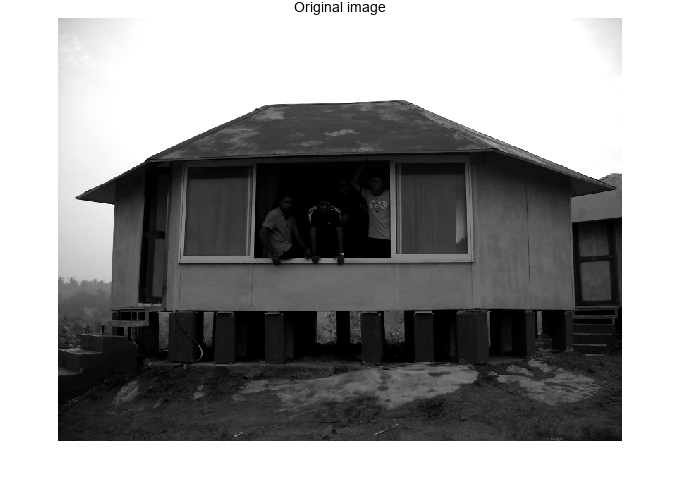

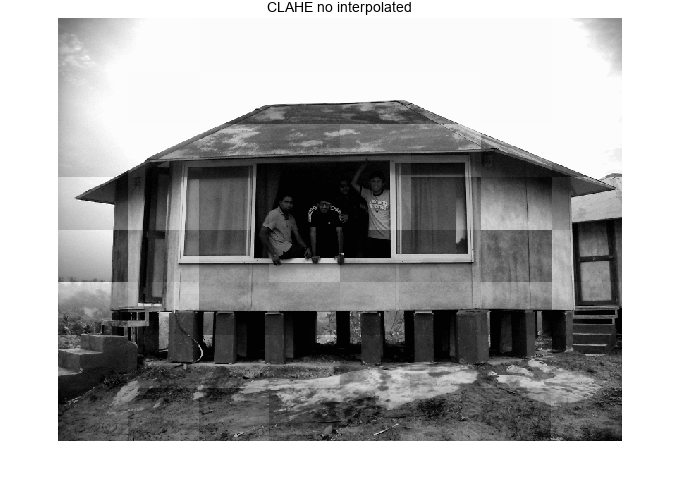

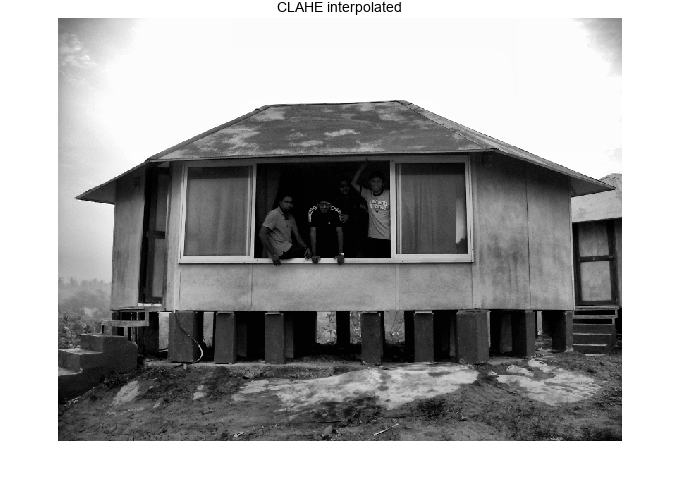

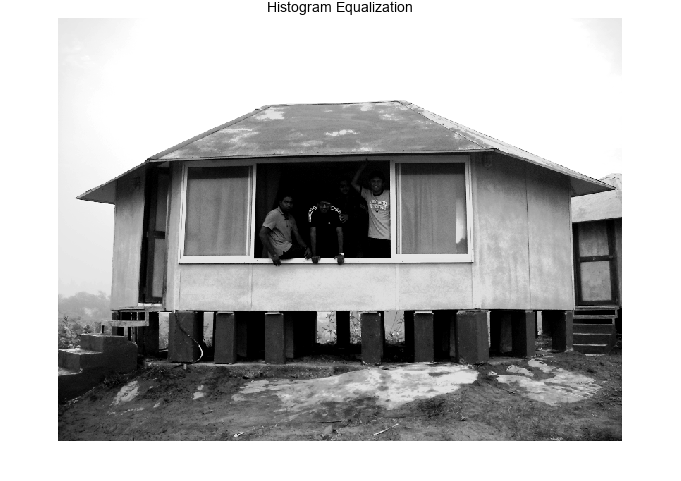

[raw, CLAHE_8, HE] = my_CLAHE('./images/man_in_house.png', 8, 0.01);

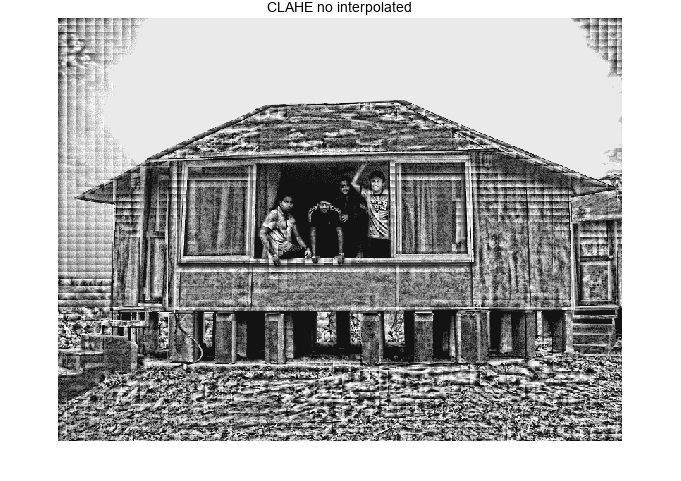

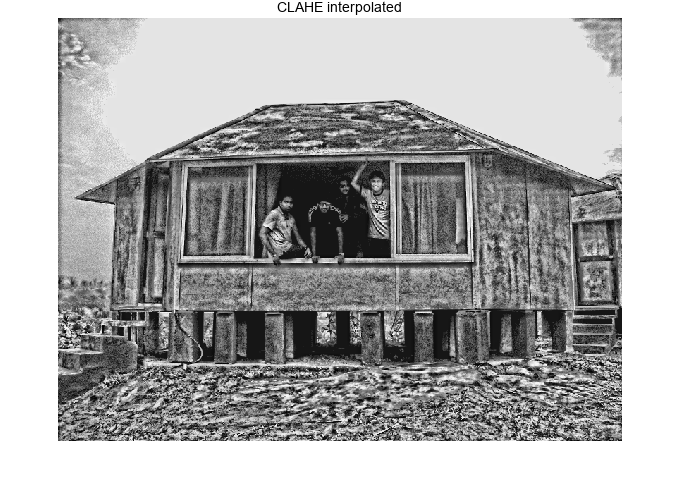

[~, CLAHE_64, ~] = my_CLAHE('./images/man_in_house.png', 64, 0.08);

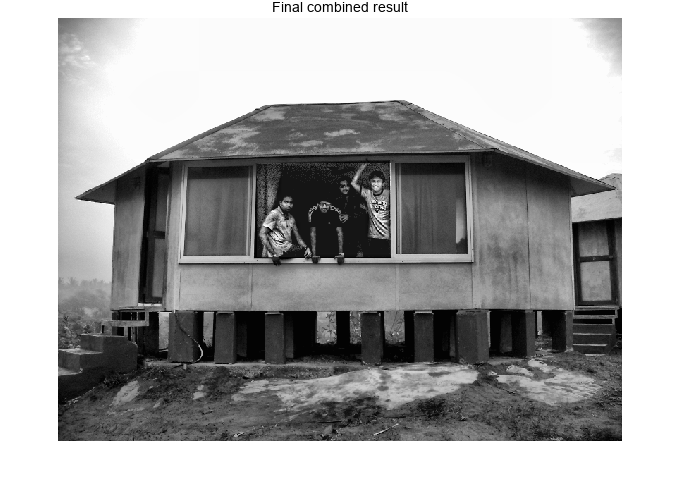

result = zeros(size(raw));
result = uint8(result);
y1=283; x1=207;
y2=472; x2=339;
for i = 1:size(result, 1)
    for j = 1:size(result, 2)
           if x1 <= i && i<= x2 && y1 <= j && j <= y2
               result(i, j)=CLAHE_64(i,j);
           else
               result(i, j)=CLAHE_8(i,j);
           end
    end
end
figure();
imshow(result);
title('Final combined result');

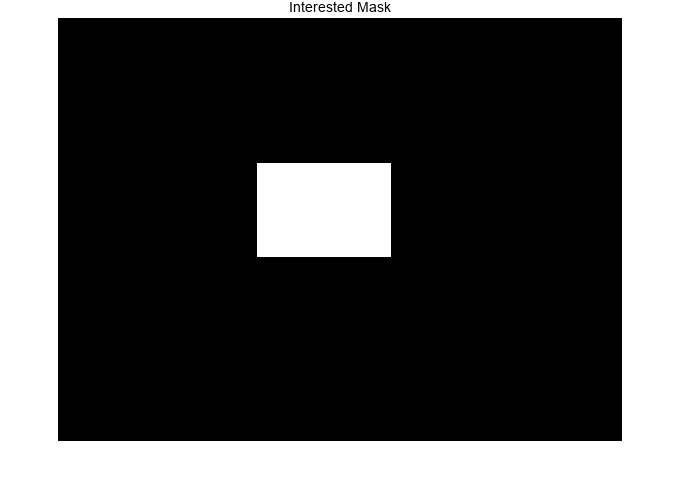

for i = 1:size(result, 1)
    for j = 1:size(result, 2)
           if x1 <= i && i<= x2 && y1 <= j && j <= y2
               result(i, j)=255;
           else
               result(i, j)=0;
           end
    end
end
figure();
imshow(result);
title('Interested Mask');

function [raw, CLAHE, HE] = my_CLAHE(path, numTiles, clipLimit)
% Read the input image
img = imread(path);

% Set the number of tiles to divide the image into
% Set the clip limit for contrast limiting

% Calculate the size of each tile
[rows, cols] = size(img);
tileSize = ceil([rows cols] / numTiles);

% Initialize the output image
outputImg = zeros(rows, cols);
% Tile center point
tile_center = zeros(numTiles, numTiles, 2);
tile_mapp   = zeros(numTiles, numTiles, 256);

% Loop through each tile
for i = 1:numTiles
    for j = 1:numTiles
        
        % Determine the current tile boundaries
        tileStartRow = (i - 1) * tileSize(1) + 1;
        tileEndRow = min(i * tileSize(1), rows);
        tileStartCol = (j - 1) * tileSize(2) + 1;
        tileEndCol = min(j * tileSize(2), cols);
        
        if tileEndRow <= tileStartRow || tileStartCol >= tileEndCol
            continue
        end

        tile_center(i, j, :) = [(tileStartRow+tileEndRow)/2, (tileStartCol+tileEndCol)/2];

        % Extract the current tile
        tile = img(tileStartRow:tileEndRow, tileStartCol:tileEndCol);
        
        
        % Calculate the histograms of the tiles
        tileHist = histcounts(tile(:),0:256);
        
        % Combine the histograms of the tiles
        combinedHist = tileHist;
        
        % Apply contrast limiting to the combined histogram
        clippedHist = combinedHist;
        numPixels = (tileEndRow - tileStartRow + 1) * (tileEndCol - tileStartCol + 1); 
        clipThreshold = clipLimit * numPixels;
        excess = clippedHist - clipThreshold;
        excess(excess < 0) = 0;
        clippedHist(clippedHist > clipThreshold) = clipThreshold;
        clippedHist = clippedHist + sum(excess) / 256;

        
        % Interpolate the histogram to get a smooth mapping function
        mappedLevels = zeros(1, 256);
        for k = 1:256
            mappedLevels(k) = sum(clippedHist(1:k));
        end
        mappedLevels = round(mappedLevels * 255 / numPixels);
        tile_mapp(i, j, :) = mappedLevels;

        % Apply the mapping function to the current tile
        for m = tileStartRow:tileEndRow
            for n = tileStartCol:tileEndCol
                outputImg(m, n) = mappedLevels(img(m, n) + 1);
            end
        end
        
    end
end
no_interpolated_outputImg = outputImg;


outputImg(:) = 0;
for i = 1:numTiles
    for j = 1:numTiles
        
        % Determine the current tile boundaries
        tileStartRow = (i - 1) * tileSize(1) + 1;
        tileEndRow = min(i * tileSize(1), rows);
        tileStartCol = (j - 1) * tileSize(2) + 1;
        tileEndCol = min(j * tileSize(2), cols);

        if tileEndRow <= tileStartRow || tileStartCol >= tileEndCol
            continue
        end

        tileCenRow = floor(tile_center(i, j, 1));
        tileCenCol = floor(tile_center(i, j, 2));

        % Perform interpolation w.r.t four center and pixel
        % LeftUp 
        LU_i = max(1, i-1);
        LU_j = max(1, j-1);
        RU_i = max(1, i-1);
        RU_j = j;
        LD_i = i;
        LD_j = max(1, j-1);
        RD_i = i;
        RD_j = j;
        for m = tileStartRow:tileCenRow
            for n = tileStartCol:tileCenCol
                x1 = tile_center(LU_i, LU_j, 1); x2=tile_center(LD_i, LD_j, 1);
                y1 = tile_center(LU_i, LU_j, 2); y2=tile_center(RU_i, RU_j, 2);
                value = img(m, n) + 1;
                if x1 == x2
                    if y1 == y2
                        outputImg(m, n) = tile_mapp(RU_i, RU_j,value);
                    else
                        outputImg(m, n) = (y2-n)/(y2-y1)*tile_mapp(LU_i, LU_j,value)+(n-y1)/(y2-y1)*tile_mapp(RU_i, RU_j,value);
                    end
                else
                    if y1 == y2
                        outputImg(m, n) = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                    else
                        r1 = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                        r2 = (x2-m)/(x2-x1)*tile_mapp(RU_i, RU_j,value)+(m-x1)/(x2-x1)*tile_mapp(RD_i, RD_j,value);
                        outputImg(m, n) = (y2-n)/(y2-y1)*r1+(n-y1)/(y2-y1)*r2;
                    end
                end
                
                %dist_LU = norm([m, n] - [tile_center(LU_i, LU_j, 1), tile_center(LU_i, LU_j, 2)]);
                %dist_RU = norm([m, n] - [tile_center(RU_i, RU_j, 1), tile_center(RU_i, RU_j, 2)]);
                %dist_LD = norm([m, n] - [tile_center(LD_i, LD_j, 1), tile_center(LD_i, LD_j, 2)]);
                %dist_RD = norm([m, n] - [tile_center(RD_i, RD_j, 1), tile_center(RD_i, RD_j, 2)]);
                
                % Calculate weights for the four neighboring centers
                %w_LU = 1 / dist_LU;
                %w_RU = 1 / dist_RU;
                %w_LD = 1 / dist_LD;
                %w_RD = 1 / dist_RD;
                %w_sum = sum([w_LU w_RU w_LD w_RD]);

                %value = img(m, n) + 1;
                %outputImg(m, n) = sum([tile_mapp(LU_i, LU_j,value) tile_mapp(RU_i, RU_j,value) tile_mapp(LD_i, LD_j,value) tile_mapp(RD_i, RD_j,value)] .* ...
                %                      [w_LU w_RU w_LD w_RD] ./ w_sum);

            end
        end

        %RightUp
        LU_i = max(1, i-1);
        LU_j = j;
        RU_i = max(1, i-1);
        RU_j = min(numTiles, j+1);
        LD_i = i;
        LD_j = j;
        RD_i = i;
        RD_j = min(numTiles, j+1);
        for m = tileStartRow:tileCenRow
            for n = tileCenCol:tileEndCol
                
                x1 = tile_center(LU_i, LU_j, 1); x2=tile_center(LD_i, LD_j, 1);
                y1 = tile_center(LU_i, LU_j, 2); y2=tile_center(RU_i, RU_j, 2);
                value = img(m, n) + 1;
                if x1 == x2
                    if y1 == y2
                        outputImg(m, n) = tile_mapp(RU_i, RU_j,value);
                    else
                        outputImg(m, n) = (y2-n)/(y2-y1)*tile_mapp(LU_i, LU_j,value)+(n-y1)/(y2-y1)*tile_mapp(RU_i, RU_j,value);
                    end
                else
                    if y1 == y2
                        outputImg(m, n) = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                    else
                        r1 = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                        r2 = (x2-m)/(x2-x1)*tile_mapp(RU_i, RU_j,value)+(m-x1)/(x2-x1)*tile_mapp(RD_i, RD_j,value);
                        outputImg(m, n) = (y2-n)/(y2-y1)*r1+(n-y1)/(y2-y1)*r2;
                    end
                end
            end
        end

        % LeftDown
        LU_i = i;
        LU_j = max(1, j-1);
        RU_i = i;
        RU_j = j;
        LD_i = min(numTiles,i+1);
        LD_j = max(1, j-1);
        RD_i = min(numTiles,i+1);
        RD_j = j;
        for m = tileCenRow:tileEndRow
            for n = tileStartCol:tileCenCol

                x1 = tile_center(LU_i, LU_j, 1); x2=tile_center(LD_i, LD_j, 1);
                y1 = tile_center(LU_i, LU_j, 2); y2=tile_center(RU_i, RU_j, 2);
                value = img(m, n) + 1;
                if x1 == x2
                    if y1 == y2
                        outputImg(m, n) = tile_mapp(RU_i, RU_j,value);
                    else
                        outputImg(m, n) = (y2-n)/(y2-y1)*tile_mapp(LU_i, LU_j,value)+(n-y1)/(y2-y1)*tile_mapp(RU_i, RU_j,value);
                    end
                else
                    if y1 == y2
                        outputImg(m, n) = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                    else
                        r1 = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                        r2 = (x2-m)/(x2-x1)*tile_mapp(RU_i, RU_j,value)+(m-x1)/(x2-x1)*tile_mapp(RD_i, RD_j,value);
                        outputImg(m, n) = (y2-n)/(y2-y1)*r1+(n-y1)/(y2-y1)*r2;
                    end
                end

            end
        end


        %RightDown
        LU_i = i;
        LU_j = j;
        RU_i = i;
        RU_j = min(numTiles, j+1);
        LD_i = min(numTiles, i+1);
        LD_j = j;
        RD_i = min(numTiles, i+1);
        RD_j = min(numTiles, j+1);
        for m = tileCenRow:tileEndRow
            for n = tileCenCol:tileEndCol

                x1 = tile_center(LU_i, LU_j, 1); x2=tile_center(LD_i, LD_j, 1);
                y1 = tile_center(LU_i, LU_j, 2); y2=tile_center(RU_i, RU_j, 2);
                value = img(m, n) + 1;
                if x1 == x2
                    if y1 == y2
                        outputImg(m, n) = tile_mapp(RU_i, RU_j,value);
                    else
                        outputImg(m, n) = (y2-n)/(y2-y1)*tile_mapp(LU_i, LU_j,value)+(n-y1)/(y2-y1)*tile_mapp(RU_i, RU_j,value);
                    end
                else
                    if y1 == y2
                        outputImg(m, n) = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                    else
                        r1 = (x2-m)/(x2-x1)*tile_mapp(LU_i, LU_j,value)+(m-x1)/(x2-x1)*tile_mapp(LD_i, LD_j,value);
                        r2 = (x2-m)/(x2-x1)*tile_mapp(RU_i, RU_j,value)+(m-x1)/(x2-x1)*tile_mapp(RD_i, RD_j,value);
                        outputImg(m, n) = (y2-n)/(y2-y1)*r1+(n-y1)/(y2-y1)*r2;
                    end
                end

            end
        end
    end
end

figure;
imshow(img, []);
title('Original image');

% Display the output image
figure;
imshow(no_interpolated_outputImg, []);
title('CLAHE no interpolated');

% Display the output image
figure();
imshow(outputImg, []);
title('CLAHE interpolated');

% Perform regular histogram equalization for comparison
histogram = zeros(1, 256);
for k = 0:255
    histogram(k+1) = sum(img(:) == k);
end
cumulativeHistogram = cumsum(histogram);
mappedLevels = round(cumulativeHistogram * 255 / numel(img));
outputImg2 = mappedLevels(img + 1);
figure();
imshow(outputImg2, []);
title('Histogram Equalization');

raw = img;
CLAHE=outputImg;
HE = outputImg2;
end
